Lawrence Lechuga

02/19/2019

# MP-574: Homework 2

## Problem 1

(Fermat's Principle)

Attached

## Problem 2

Suppose we want to minimize a quadratic function, f(x): 


$$f\left(x\right)=\frac{1}{2}x^T \cdot Q\cdot x-x^T \cdot b$$



$${\mathrm{argmin}}_{\mathrm{X}} \left\lbrace f\left(x\right)\right\rbrace$$


Q is a symmetric positive definite matrix $\;Q=Q^T >0$ and some vector **b**. Where $Q=A^T \cdot C\cdot A$


$$A=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
0 & 2 & 1\\
4 & 0 & 1
\end{array}\right\rbrack$$
         
$$C=\left\lbrack \begin{array}{ccc}
400 & 0 & 0\\
0 & 20 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$
         
$$B=\left\lbrack \begin{array}{c}
100\\
100\\
100
\end{array}\right\rbrack$$


% initialize matrices and function
clear all
A = [1,2,3; 0,2,1; 4,0,1]; 
C = [400,0,0; 0,20,0; 0,0,1];
B = [100;100;100];
Q = A'*C*A;
iters = 80;
X = zeros(3,iters+1);
f = @(x) (1/2*x'*Q*x-x'*B) % function to minimize

f = function_handle with value:
    @(x)(1/2*x'*Q*x-x'*B)

df = @(x) (Q*x-B);

### Part A

Steepest decent follows that each step should move in the negative gradient direction.


$$x^{\left(k+1\right)} =x^{\left(k\right)} -\alpha \cdot \nabla f\left(x^{\left(k\right)} \right)$$


where $\alpha$ is the step size that can be determined by a golden section search, with an initial search range of [0,1] (i.e. $a_0 =0;b_0 =1$).

alpha = zeros(1,iters)

alpha =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


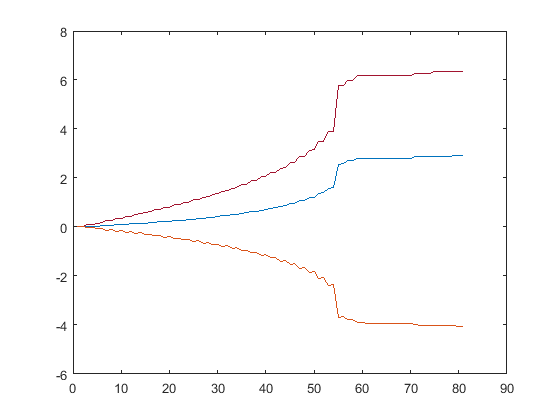

for ii=1:iters
    a0 = 0;
    b0 = 1;
    alpha_iters = 1000;
    alpha(ii) = goldensearch(f,df,X(:,ii),a0,b0,alpha_iters);
    X(:,ii+1) = X(:,ii) - alpha(ii)*df(X(:,ii));
end 
iterations = (1:iters+1);
title('Solution vs Iteration')
F = zeros(3,iters+1);
for jj=1:iters+1
    F(:,jj) = f(X(:,jj));
end 
plot(iterations,X,iterations,X,iterations,X);

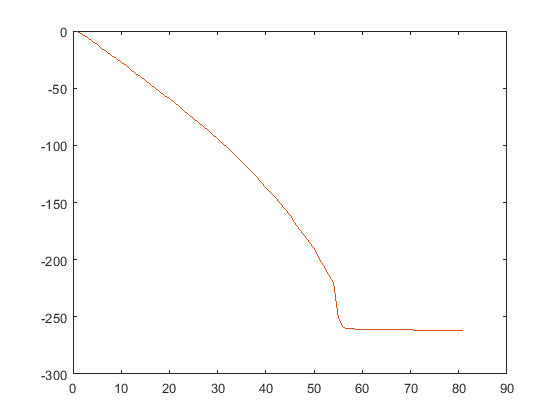

plot(iterations,F,iterations,F,iterations,F);

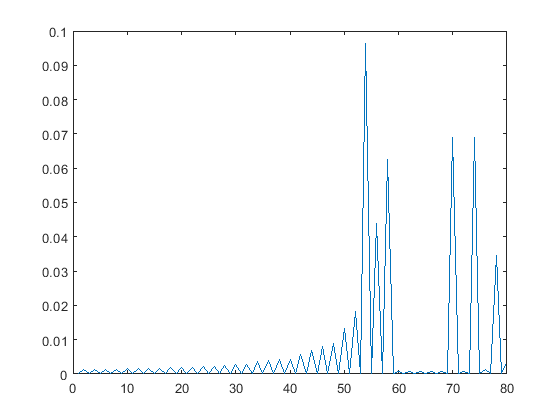

plot(alpha)

### Part B